error_L1 = 0.0454

error_L2 = 0.0908

error_Linf = 0.1817

error_L1 = 0.0182

error_L2 = 0.0252

error_Linf = 0.0498

error_L1 = 0.0050

error_L2 = 0.0065

error_Linf = 0.0128

error_L1 = 0.0013

error_L2 = 0.0016

error_Linf = 0.0032

error_L1 = 3.2604e-04

error_L2 = 4.0821e-04

error_Linf = 8.0280e-04

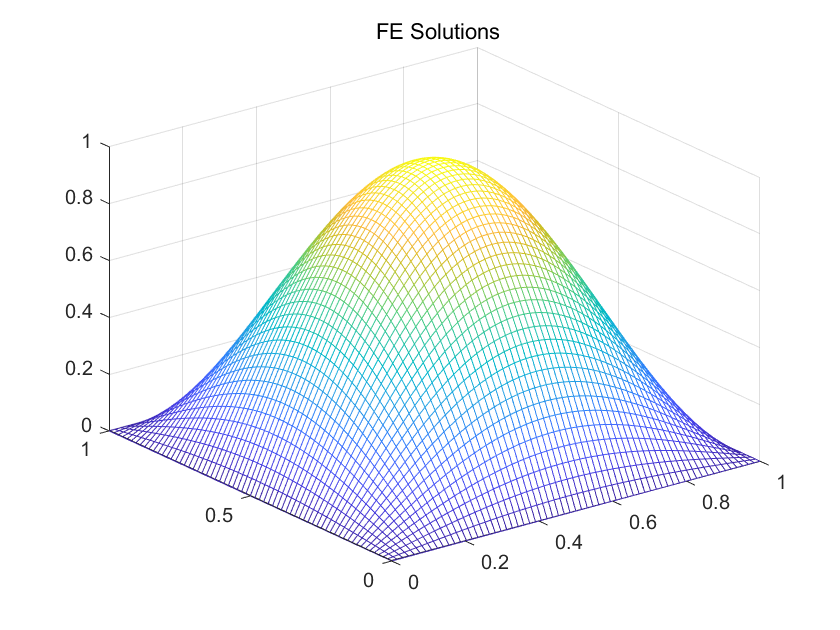

error_L1 = 8.1659e-05

error_L2 = 1.0210e-04

error_Linf = 2.0077e-04

error_L2s = [];
for k = [2,4,8,16,32,64]
Lx = 1; %定义单元右边界（左边界为0，如果不是，可以平移为0）
Ly = 1;%定义单元上边界
N = k;%分割的一个方向的单元数目
numelx = N;%定义分割的x方向单元数目（按矩形计算）
numely = N;%定义分割的y方向单元数目（按矩形计算）
hx = Lx/numelx;%x方向上的单元长度（对应着三角形两条直角边之一）
hy = Ly/numely;%y方向上的单元长度（对应着三角形两条直角边之一）
numel = numelx*numely*2;%小单元的数目,每个矩形分成两个三角形
u_b = zeros(2*(numelx+numely),1); %定义第一类边界条件，一圈过来都是0
numnodx = numelx + 1; % x方向节点个数比单元个数多1
numnody = numely + 1; % y方向节点个数比单元个数多1
numnod = numnodx*numnody;%总的节点个数
nel = 3;%每个单元的节点数目,即每个单元上有几个形函数参与作用，单元自由度
coordx = linspace(0,Lx,numnodx)'; %等分节点的坐标（为了方便，我这里采用等分的方式，事实上单元长度可以不一致，非均匀网格）
coordy = linspace(0,Ly,numnody)'; %等分节点的坐标（为了方便，我这里采用等分的方式，事实上单元长度可以不一致）
[X, Y] = meshgrid(coordx,coordy);%张成网格，X和Y分别表示对应位置的横纵坐标
X = X';Y = Y';coord = [X(:) Y(:)];%把网格一行一行扯开，coord的每一行是对应节点的坐标，按顺序排
connect = connect_mat(numnodx,numnody,nel);%连接矩阵，表示每个单元周围的节点编号，也就是涉及的形函数编号
ebcdof = unique([1:numnodx numnodx*numely+1:numnodx*numely+numnodx ...
    numnodx+1:numnodx:numnodx*(numely-1)+1 2*numnodx:numnodx:numely*numnodx]); % 强制性边界点的编号，本例子中是四条边，下上左右边
ebcval = u_b; %假设边界值都为u_b
bigk = sparse(numnod,numnod); % 刚度矩阵[K]，初始化为0，使用稀疏矩阵存储
fext = sparse(numnod,1);      % 载荷向量{f},初始化为0

%%  计算系数矩阵K和右端项f，单刚组装总刚
for e = 1:numel %同一维的情况，依然按单元来扫描
  ke = elemstiff2d(e,nel,hx,hy,coord,connect);%计算单元刚度矩阵
  fe = elemforce2d(e,nel,hx,hy,coord,connect);%计算单元载荷向量
  sctr = connect(e,:);
  bigk(sctr,sctr) = bigk(sctr,sctr) + ke;
  fext(sctr) = fext(sctr) + fe;
  %full(bigk)
  %full(fext)
end
for i = 1:length(ebcdof)
  n = ebcdof(i);
  for j = 1:numnod
    if (isempty(find(ebcdof == j, 1))) % 第j个点若不是固定点
      fext(j) = fext(j) - bigk(j,n)*ebcval(i);
    end
  end
  bigk(n,:) = 0.0;
  bigk(:,n) = 0.0;
  bigk(n,n) = 1.0;
  fext(n) = ebcval(i);
end
u_coeff = bigk\fext;%求出系数，事实上也是函数在对应点上的值
u_cal = u_coeff;
u_cal_re = reshape(u_coeff,numnodx,numnody);
u_cal_re = full(u_cal_re);

%% 求精确解
L =Lx;
nsamp = 1001;
xsamp = linspace(0,L,nsamp);%100等分区间中间有100个数
[X,Y] = meshgrid(xsamp,xsamp);
uexact = exactsolution2d(X(:),Y(:));
uexact_re = reshape(uexact,nsamp,nsamp);
mesh(xsamp,xsamp,uexact_re)
%% 绘图，可视化
h = mesh(coordx,coordy,u_cal_re);
title(' FE Solutions');%标题
%% 求精确解，计算误差，没有计算单元准确积分，依然使用近似误差

u_ex = exactsolution2d(coord(:,1),coord(:,2));
u_ex_re = reshape(u_ex,numnodx,numnody);
error_L1 = sum(abs(u_cal - u_ex))*hx*hy
error_L2 = sqrt(sum((u_cal - u_ex).^2)*hx*hy)
error_Linf = max(abs(u_cal - u_ex))
error_L2s(end+1) = error_L2;

end

es = log2(error_L2s(1:end-1)./error_L2s(2:end))

es =     1.8507    1.9596    1.9900    1.9975    1.9994


function [ke] = elemstiff2d(e,nel,hx,hy,coord,connect)
T = hx*hy/2;
ke    = zeros(nel,nel); %单刚初始化
nodes = connect(e,:);%相关形函数（节点）编号
xe    = coord(nodes,:); %相关节点的坐标
xi1 = xe(2,1) - xe(3,1);xi2 = xe(3,1) - xe(1,1);%xi3 = xe(1,1) - xe(2,1);
eta1 = xe(2,2) - xe(3,2);eta2 = xe(3,2) - xe(1,2);%eta3 = xe(1,2) - xe(2,2);
auv11 = -((eta1*xi2 - eta2*xi1)*(eta1^2 + eta2^2))/(8*T^2);
auv12 = ((eta1*xi1 + eta2*xi2)*(eta1*xi2 - eta2*xi1))/(8*T^2);
auv13 = -((eta1*xi2 - eta2*xi1)*(- eta1^2 + xi1*eta1 - eta2^2 + xi2*eta2))/(8*T^2);
auv22 = -((xi1^2 + xi2^2)*(eta1*xi2 - eta2*xi1))/(8*T^2);
auv23 = -((eta1*xi2 - eta2*xi1)*(- xi1^2 + eta1*xi1 - xi2^2 + eta2*xi2))/(8*T^2);
auv33 = -((eta1*xi2 - eta2*xi1)*(eta1^2 - 2*eta1*xi1 + eta2^2 - 2*eta2*xi2 + xi1^2 + xi2^2))/(8*T^2);
ke = ke + [auv11 auv12 auv13;auv12 auv22 auv23;auv13 auv23 auv33];
return
end



function [fe] = elemforce2d(e,nel,hx,hy,coord,connect)
%输入单元编号e，单元自由度nel数目，单元长度hx，单元宽度hy，单元节点坐标coord，和连接矩阵connect
%输出单元载荷fe
%考虑以一般单元为基准，可求f在这个一般单元上的取值，再在这个一般单元上积分
%比较规范的划分，求积分不妨直接在一般单元上求，没必要变换到标准单元上，一来若求梯度更加麻烦了，标准单元上的依然需要求不同的积分
%二来因为f的值未定，依然需要求积分
%fe = zeros(nel,1); %初始化载荷向量
nodes = connect(e,:);%自由度编号
xe = coord(nodes,:); % 单元自由节点坐标
xi1 = xe(2,1) - xe(3,1);xi2 = xe(3,1) - xe(1,1);%xi3 = xe(1,1) - xe(2,1);
eta1 = xe(2,2) - xe(3,2);eta2 = xe(3,2) - xe(1,2);%eta3 = xe(1,2) - xe(2,2);
%syms lam1 lam2;


%x =  xe(3,1) + lam1*(-xi2)+lam2*(xi1);
%y =  xe(3,2) + lam1*(-eta2)+lam2*(eta1);


detJ = eta2*xi1 - eta1*xi2;
g1 = @(lam1,lam2) fun(xe(3,1) + lam1*(xi2)+lam2*(xi1),xe(3,2) + lam1*(-eta2)+lam2*(eta1)).*lam1*detJ;%g1 = matlabFunction(g1);
g2 = @(lam1,lam2) fun(xe(3,1) + lam1*(xi2)+lam2*(xi1),xe(3,2) + lam1*(-eta2)+lam2*(eta1)).*lam2*detJ;%g2 = matlabFunction(g2);
g3 = @(lam1,lam2) fun(xe(3,1) + lam1*(xi2)+lam2*(xi1),xe(3,2) + lam1*(-eta2)+lam2*(eta1)).*(1-lam1-lam2)*detJ;%g3 = matlabFunction(g3);

lammax = @(lam1) 1 - lam1;
gx(1) = integral2(g1,0,1,0,lammax);
gx(2) = integral2(g2,0,1,0,lammax);
gx(3) = integral2(g3,0,1,0,lammax);
fe = [gx(1);gx(2);gx(3)];
end

function bx = fun(x,y)
bx = (2*pi^2)*sin(pi*x).*sin(pi*y);
end




function connect_mat = connect_mat( numnodx,numnody,nel)
%输入横纵坐标的节点数目，和单元自由度
%输出连接矩阵，每个单元涉及的节点的编号
xn = 1:(numnodx*numnody);%拉成一条编号
A = reshape(xn,numnodx,numnody);%同形状编号
for i = 1:(numnodx-1)*(numnody-1)
    xg = rem(i,numnodx-1);%xg表示单元为左边界数起第几个
    if xg == 0
        xg = numnodx-1;
    end
    yg = ceil(i/(numnodx-1));%下边界其数第几个
    a = A(xg:xg+1,yg:yg+1);%这个小矩阵，拉直了就是连接矩阵
    a_vec = a(:);
    connect_mat(2*i-1:2*i,1:nel) = [a_vec([1 4 3])';a_vec([4 1 2])'];
end
end

function uexact = exactsolution2d(xg,yg)
uexact = sin(pi*xg).*sin(pi*yg);

return
end